**Reading test Image**

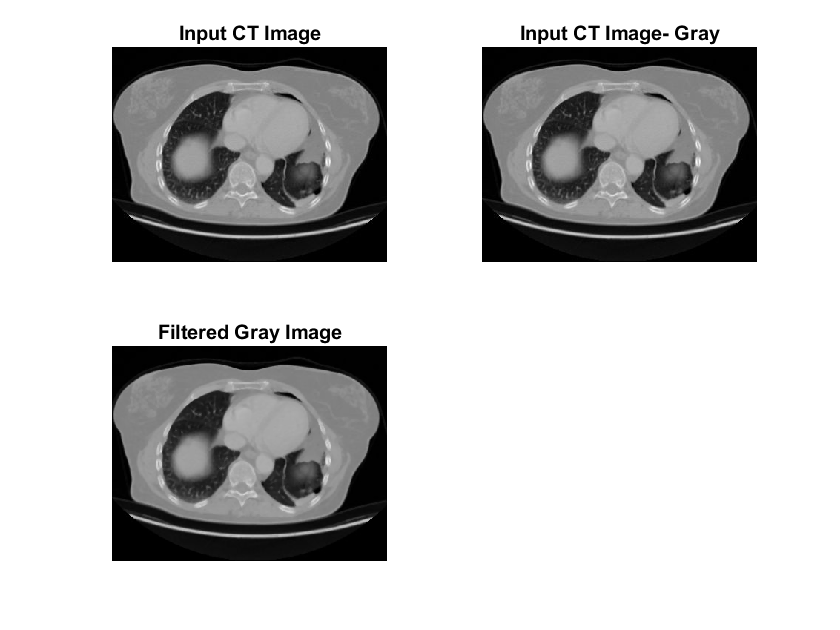

clc;clear;close all;
input_img=imread('97.jpg');
figure;subplot(221);imshow(input_img);
title('Input CT Image');
input_gray=im2gray(input_img);
subplot(222);imshow(input_gray);
title('Input CT Image- Gray');
medfiltered=medfilt2(input_gray,[3,3]);
subplot(223);imshow(medfiltered);
title('Filtered Gray Image');

**Image Analysis**

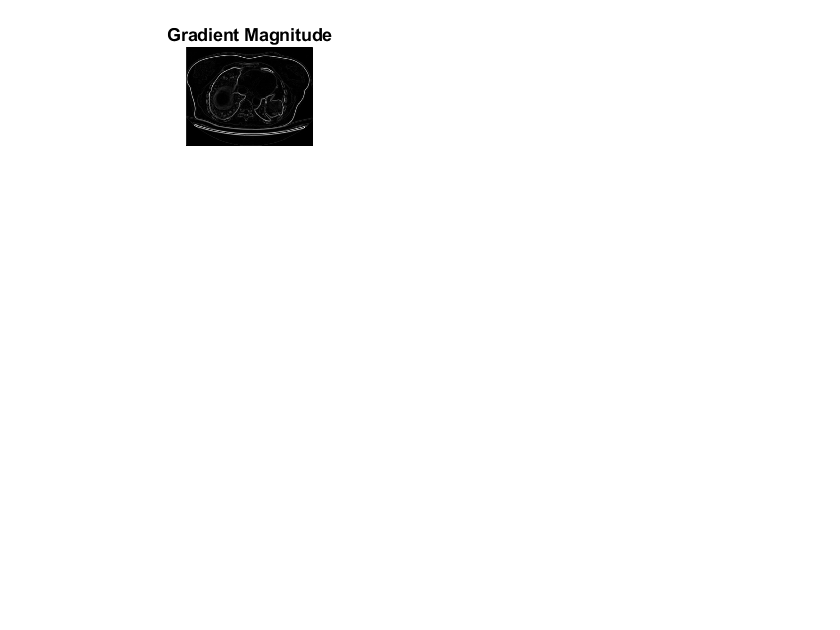

[Gx,Gy]=imgradientxy(medfiltered);
[Gmag,Gdir] = imgradient(Gx,Gy);
figure;subplot(421);imshow(Gmag,[]), title('Gradient Magnitude')

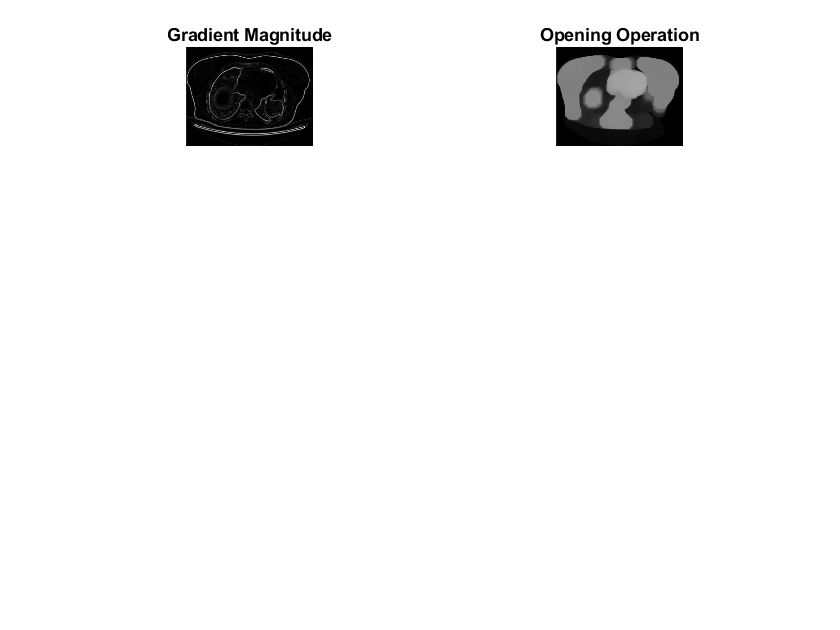

se = strel('disk', 20);
openedimg = imopen(medfiltered, se);
subplot(422);imshow(openedimg), title('Opening Operation')

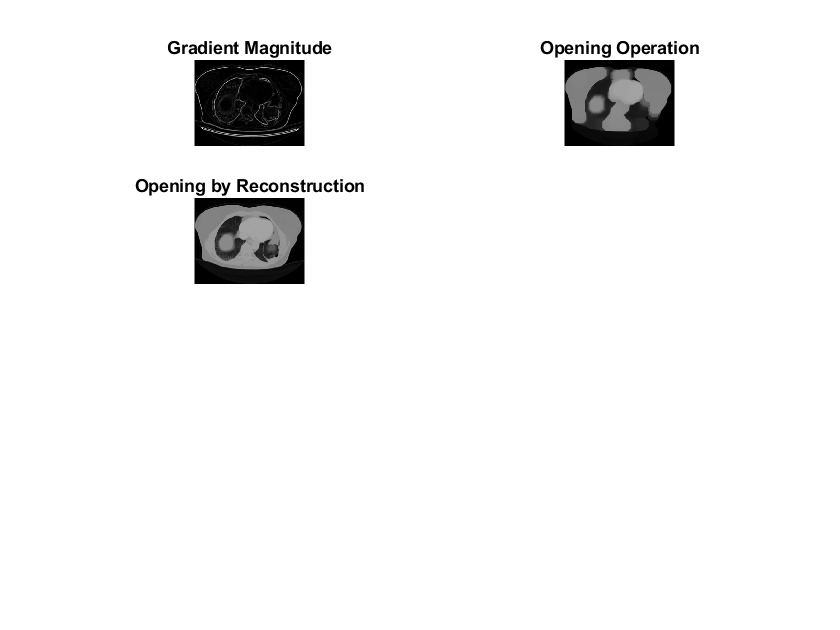

erodedimg = imerode(medfiltered, se);
reconstrimg = imreconstruct(erodedimg, medfiltered);
subplot(423);imshow(reconstrimg), title('Opening by Reconstruction')

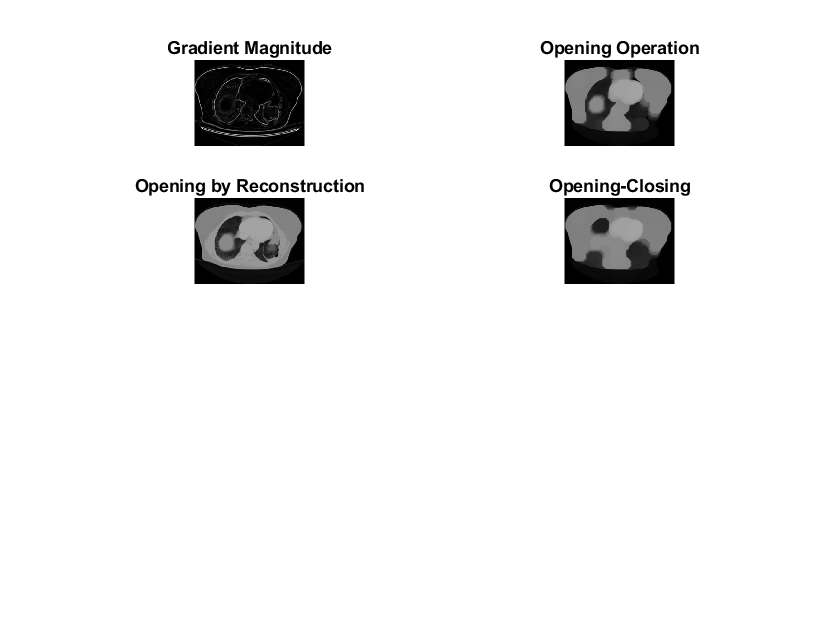

closedimg = imclose(openedimg, se);
subplot(424);imshow(closedimg), title('Opening-Closing')

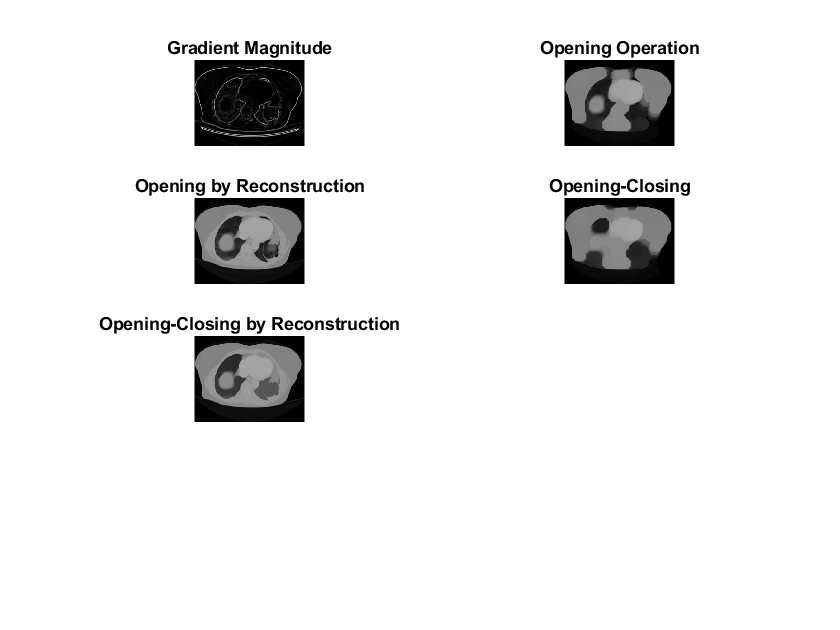

dilatedimg = imdilate(reconstrimg, se);
reconstructandcomp = imreconstruct(imcomplement(dilatedimg), imcomplement(reconstrimg));
reconstructandcomp = imcomplement(reconstructandcomp);
subplot(425);imshow(reconstructandcomp), title('Opening-Closing by Reconstruction')

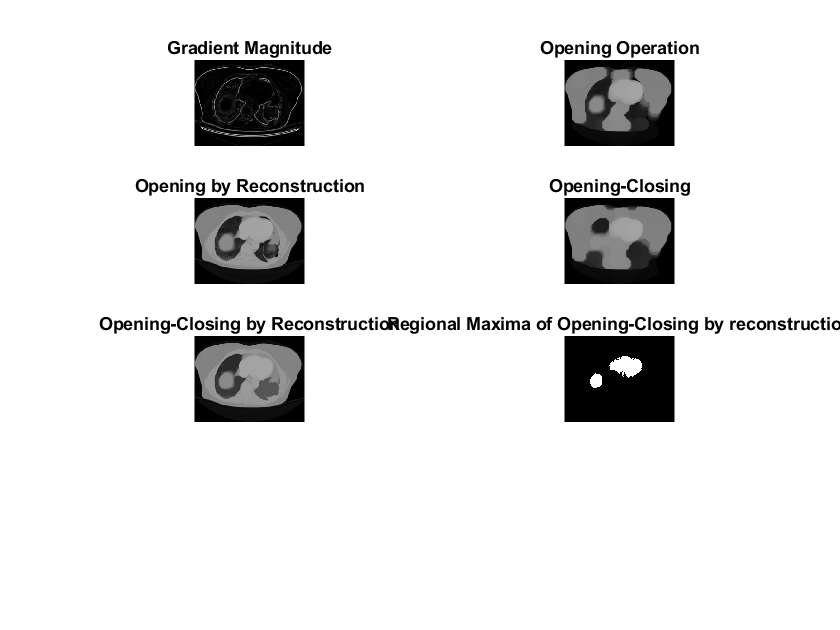

regionmax = imregionalmax(reconstructandcomp);
subplot(426);imshow(regionmax), title('Regional Maxima of Opening-Closing by reconstruction')

se2 = strel(ones(5,5));
regionmaxclose = imclose(regionmax, se2);
regionmaxcloseerode = imerode(regionmaxclose, se2);
regionmaxareaopen = bwareaopen(regionmaxcloseerode, 20);

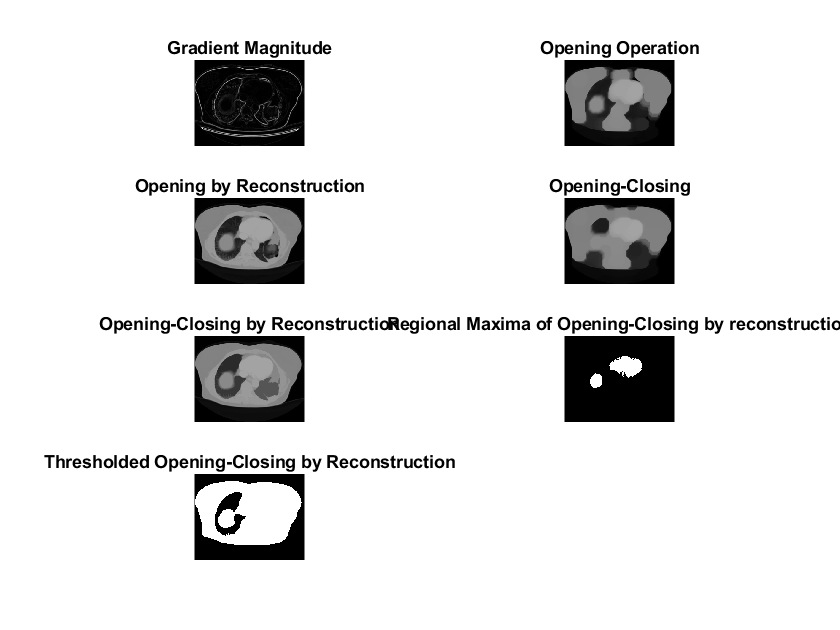

binaryimg = imbinarize(reconstructandcomp);
subplot(427);imshow(binaryimg), title('Thresholded Opening-Closing by Reconstruction')

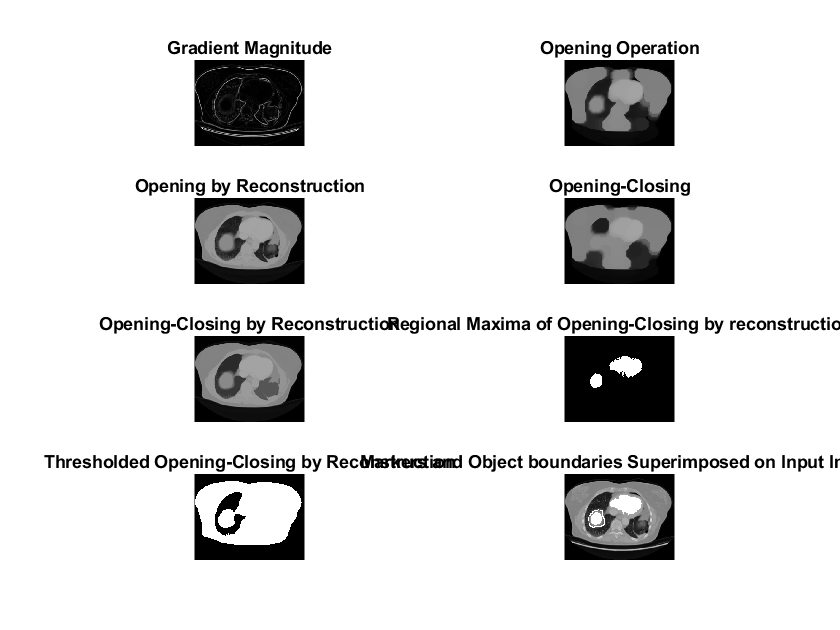

disttrans = bwdist(binaryimg);
watershedimg = watershed(disttrans);
bgm = watershedimg == 0;
gradmag2 = imimposemin(Gmag, bgm | regionmaxareaopen);
L = watershed(gradmag2);
I4 = medfiltered;
I4(imdilate(L == 0, ones(3, 3)) | bgm | regionmaxareaopen) = 255;
subplot(428);imshow(I4);title('Markers and Object boundaries Superimposed on Input Image')

**Extracting Features of Input Image for Classification**

%Noise Removal
x = double(regionmax);
signal1 = regionmax(:,:);

[cA1,cH1,cV1,cD1] = dwt2(signal1,'db4');
[cA2,cH2,cV2,cD2] = dwt2(cA1,'db4');
[cA3,cH3,cV3,cD3] = dwt2(cA2,'db4');
DWT_feat = [cA3,cH3,cV3,cD3];

%Pre-Processing Extracted Data
G = pca(DWT_feat);

%Extracting GLCM features
g = graycomatrix(G);
stats = graycoprops(g,'Contrast Correlation Energy Homogeneity');
Contrast = stats.Contrast

Contrast = 0.2184

Correlation = stats.Correlation

Correlation = 0.1222

Energy = stats.Energy

Energy = 0.8816

Homogeneity = stats.Homogeneity

Homogeneity = 0.9657


%Mean,SD,Entropy,RMS,Var
Mean = mean2(G)

Mean = 0.0025

Standard_Deviation = std2(G)

Standard_Deviation = 0.0693

Entropy = entropy(G)

Entropy = 1.9679

RMS = mean2(rms(G))

RMS = 0.0693

Variance = mean2(var(double(G)))

Variance = 0.0048

a = sum(double(G(:)));
Smoothness = 1-(1/(1+a));
Kurtosis = kurtosis(double(G(:)))

Kurtosis = 28.2443

Skewness = skewness(double(G(:)))

Skewness = 2.2241

% Inverse Difference Movement
m = size(G,1);
n = size(G,2);
in_diff = 0;
for i = 1:m
    for j = 1:n
        temp = G(i,j)./(1+(i-j).^2);
        in_diff = in_diff+temp;
    end
end
IDM = double(in_diff)

IDM = 1.3861

feat = [Contrast,Correlation,Energy,Homogeneity, Mean, Standard_Deviation, Entropy, RMS, Variance, Smoothness, Kurtosis, Skewness, IDM];

**Loading Data File for Training Model **

[Training Dataset and Custom Feature Extraction Program to Generate training_dataset.xlsx](https://iitkgpacin-my.sharepoint.com/:f:/g/personal/aravindsri30_kgpian_iitkgp_ac_in/Ev4_fCkna-tFvE_Z2MDyVXABAaXTxXKeDMV-DAia1srLUA?e=FRbeOr)

db = xlsread('training_dataset.xlsx');
Contrast = db(1:end,1);
Correlation = db(1:end,2);
Energy = db(1:end,3);
Homogeneity = db(1:end,4);
Mean = db(1:end,5);
Standard_Deviation = db(1:end,6);
Entropy = db(1:end,7);
RMS = db(1:end,8);
Variance = db(1:end,9);
Smoothness = db(1:end,10);
Kurtosis = db(1:end,11);
Skewness = db(1:end,12);
IDM = db(1:end,13);
features_train = ([Contrast,Correlation,Energy,Homogeneity, Mean, Standard_Deviation, Entropy, RMS, Variance, Smoothness, Kurtosis, Skewness, IDM]);
class = db(1:end,14);

**Model Definition **

svmStruct= fitcsvm(features_train,class,"KernelFunction","gaussian",'PolynomialOrder', [], ...
'KernelScale', 0.9399999999999999, ...
'BoxConstraint', 1, ...
'Standardize', true, ...
'ClassNames', [0; 1]);

**Classifying Input Image**

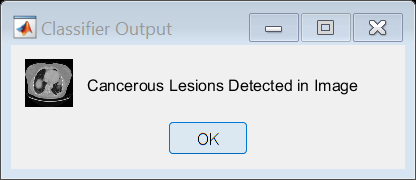

[lung_cancer] = predict(svmStruct,[feat]);
if (lung_cancer==1)
op=msgbox('Cancerous Lesions Detected in Image','Classifier Output','custom',input_img);
else
op=msgbox('NO Cancerous Lesions Detected in Image','Classifier Output','custom',input_img);
end


predictorNames = {'imageName', 'Contrast', 'Correlation', 'Energy', 'Homogeneity', 'Mean', 'Standard_Deviation', 'Entropy', 'RMS', 'Variance', 'Smoothness', 'Kurtosis', 'Skewness', 'IDM'};
predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(feat) predict(svmStruct, feat);
trainedClassifier.predictFcn = @(feat) svmPredictFcn(predictorExtractionFcn(feat));% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'Contrast', 'Correlation', 'Energy', 'Entropy', 'Homogeneity', 'IDM', 'Kurtosis', 'Mean', 'RMS', 'Skewness', 'Smoothness', 'Standard_Deviation', 'Variance', 'imageName'};
trainedClassifier.svmStruct = svmStruct;
partitionedModel = crossval(trainedClassifier.svmStruct, 'KFold', 5);% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
Accuracy=abs(validationAccuracy*100);
fprintf('Model Accuracy is %4.2f',Accuracy);

Model Accuracy is 97.88